# Test deep learning model on new animal images

## Objective: Classify types of wild animals from images

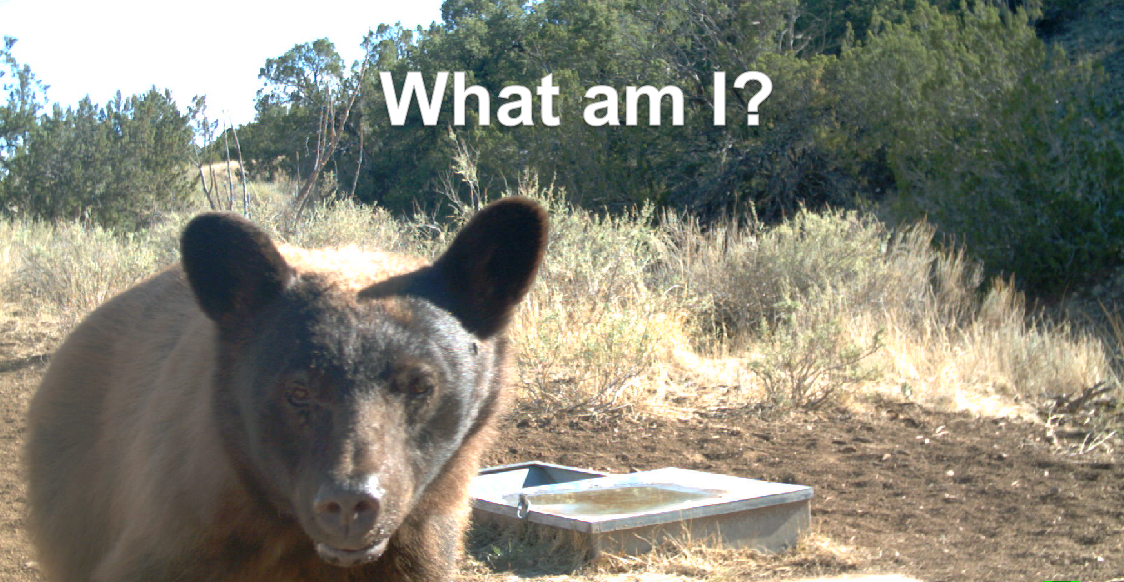

Article describing the example:

[https://www.mathworks.com/company/newsletters/articles/an-experiment-in-deep-learning-with-wild-animal-trail-camera-data.html](https://www.mathworks.com/company/newsletters/articles/an-experiment-in-deep-learning-with-wild-animal-trail-camera-data.html)

The model was trained using the following example with Inception v3 network: 

[https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html)

Details on Inception V3 architecture found in this paper: [https://arxiv.org/abs/1512.00567](https://arxiv.org/abs/1512.00567)

## Select and load network

To test the network, ***you'll need ***[inceptionv3 ](https://www.mathworks.com/matlabcentral/fileexchange/65679-deep-learning-toolbox-model-for-inception-v3-network)***(from Add-on Explorer)***

[https://www.mathworks.com/solutions/deep-learning/models.html](https://www.mathworks.com/solutions/deep-learning/models.html)

Hint: if you execute this line: `net = inceptionv3();` the error message will provide a link to the correct add-on ;)

### Choose type of model

Select the model to test:

- Bear/ not bear

- Barbary sheep vs bighorn sheep

- 40 types of animals

load("bearNoBearNetwork.mat")

## Classify new images

### Read image(s)

Type file or directory location below and number of images to test. 

mydir = "../Animals/" + ["bear","dog","barbary sheep","cow"];
numImages = 50;

ds = imageDatastore(mydir,...
    "IncludeSubfolders",true); 
fnames = ds.Files;

Select random files to include in subset. (use `splitEachLabel` if using class labels)

% rng(42)  % repeatable to test
idx = randperm(length(fnames),numImages);
ds2 = subset(ds,idx);

### Resize images for network

Get the input size from the network and resize through `augmentedImageDatastore`:

inputSize = net.Layers(1).InputSize(1:2);
augds = augmentedImageDatastore(inputSize,ds2);

### Classify type of animal

Perform classification

[predictedLabel,prob] = classify(net,augds);

## Visualize some predictions

Select random images to visualize classifications

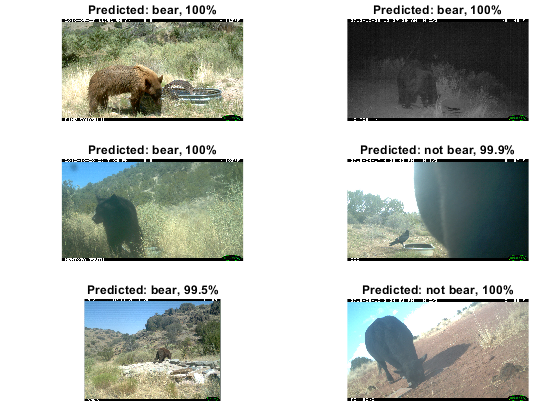

n = 6;
 
plotAnimalPredictions(ds2,n,predictedLabel,prob)

**Helper function**

function plotAnimalPredictions(ds,n,predictedLabel,prob)

fnames = ds.Files;
idx = randperm(length(fnames),n);
figure
t = tiledlayout("flow");
for i = 1:n    
    I = readimage(ds,idx(i));
    nexttile;
    imshow(I)
    label = predictedLabel(idx(i));
    title(["Predicted: "+ string(label) + ", " + ...  
        num2str(100*max(prob(idx(i),:)),3) + "%"],...
        "Interpreter","none");                              %#ok
end
t.TileSpacing = "none";
t.Padding = "none";

end